# FEM for 2-D TM scattering from a dielectric cylinder (6 hours)

In this lab, we will solve the 2-D electromagnetic problem of the scattering of a TM$^z$ plane wave on a dielectric cyinder with circular cross section and whose axis is aligned along the $z$ direction. 

The cylinder cross section has radius $r$, such that its circunference is one free-space wavelength: $kr=1$

The computational domain is truncated with a circle of radius $a$.

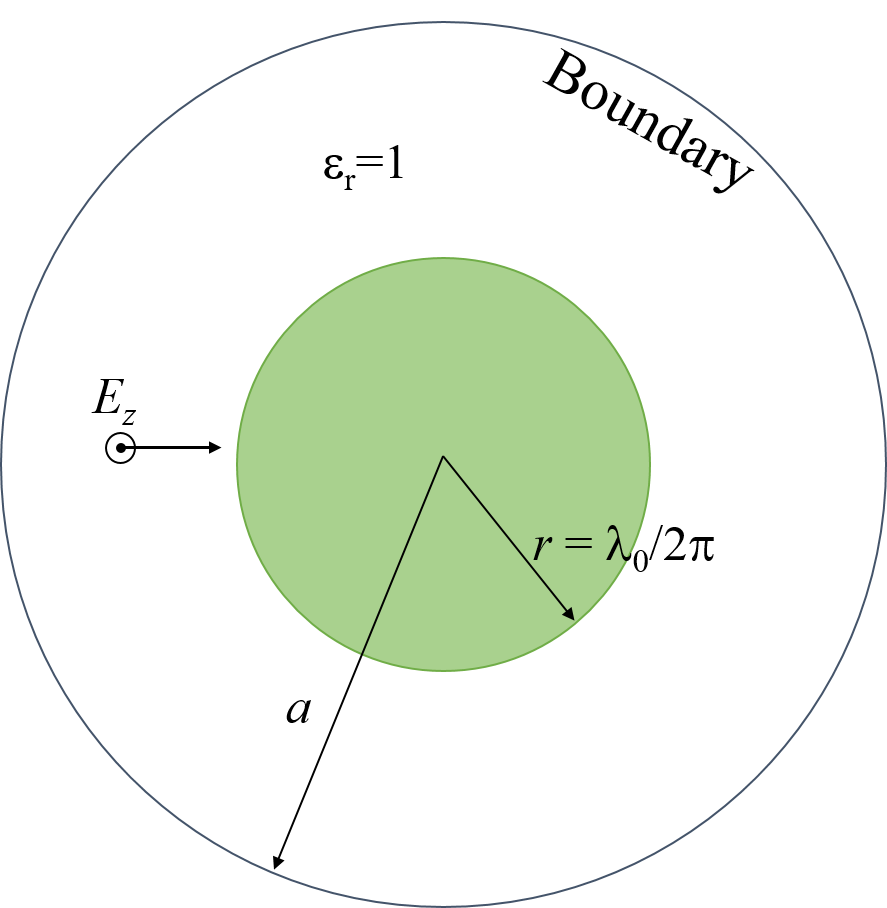

close all; clearvars

## 1 Definition of fundamental variables

c   = 3d8;               % Light velocity in vacuum
mu0 = 4*pi*1.d-7;        % Vacuum magnetic permeability
eps0= 1.d-9/(36*pi);     % Vacuum dielectric permettivity

f = 3d8;                 % Plane-wave frequency (0.3 GHz)
k = 2*pi*f/c;            % Free-space wavenumber
lambda0 = c/f;           % Wavelength in vacuum
theta_inc = 0*(pi/180);  % Incident angle of the incident plane wave with respect to the x axis

## 2 Studying the mesh and the geometry

Here we import and study the data describing the mesh of the domain to simulate.

We have two meshes, a coarser mesh (29 nodes) and a finer mesh (51 nodes).

The data for each mesh are contained in the files "FEM_XXnodes.mat".

The 29-node model is truncated with a circular boundary of radius $a=0.25\lambda_0$. The 51-node model is truncated with a circular boundary of radius $a=0.22\lambda_0$.

### 2.1 Loading the mesh data

The mesh data are contained in four variables:

- "faces": it is the **connectivity array**, made of  four columns. Each row is associated to a triangular element. The first three columns are the numbers of its vertices. The fourth column is the dielectric constant of the element.

- "vertices": it is an array of two columns. Each row is associated to a node. The first column is its $x$ coordinate, the second column is its $y$ coordinate.

- "boundary": it is an array of all the nodes on the circular external boundary.

- "faces_plot": it is the connectivity array without the column of the dielectric constants. It is used by the Matlab commant "triplot" to draw the model.

After loading the data, compute the number of faces, the number of nodes (vertices) and the number of nodes on the boundary in the following code box.

load('FEM_29nodes.mat'); a = 0.25*lambda0;
% load('FEM_51nodes.mat'); a = 0.22*lambda0;

no_faces = size(faces,1);         % Number of triangular faces
no_vertices =size(vertices,1);      % Number of nodes
no_boundary =size(boundary,2);       % Number of nodes on the geometry boundary

### 2.2 Plotting the mesh

We can use the command "triplot" to plot the mesh. Remember to use the array "faces_plot".

Once the mesh is plotted, put on the same plot also the labels of the nodes. You can use the command "text" with the coordinates of each node and the label number (converted into a string). Use the options 'HorizontalAlignment','right'.

Put a red asterisk on the nodes belonging to the boundary. You can use the command "plot" with each node coordinates, and the option "r*" for the red asterisk.

Finally, display the triangle label (in blue) inside each triangle. The coordinate of the center of the each triangle can be taken as the average of the coordinates of its vertices:

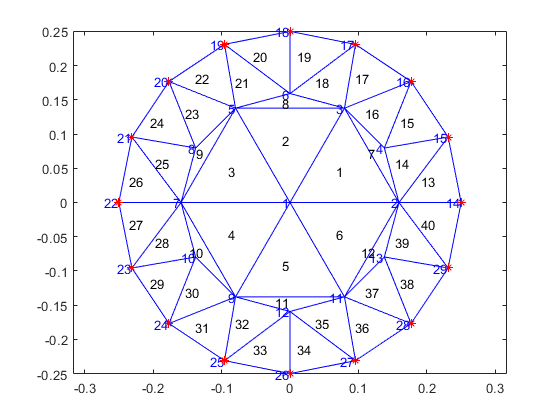

% Plotting the mesh
figure(1)
X=vertices(:,1);
Y=vertices(:,2);
triplot(faces_plot,X,Y);
axis equal
hold on

% Remember: to display a number x at the point (A,B):
text(X,Y,string(1:no_vertices),'HorizontalAlignment','right','Color','blue');hold on;

plot(X(boundary),Y(boundary),"r*");hold on;

text(mean(X(faces_plot),2),mean(Y(faces_plot),2),string(1:no_faces),'HorizontalAlignment','right')

Take the time now to open the data and check that they are coherent with the geometry plotted.

Identify the dielectric circle in the plot.

## 3 Matrix entries: integral computation

Now we compute the FEM matrix. 

- First of all, we inzialize the matrix to zero.

- We perform a loop over the triangles.

- For each triangle we fill two 3x3 matrices. One matrix contains the integrals of the product of two basis functions associated to two vertices. The second matrix contains the integrals of the product of the *gradients* of two basis functions associated to two vertices.

- The $(i,j)$ entry of each matrix is the integral coming from the basis functions associated to the vertices $i$ and $j$ ($i=1,2,3$ and $j=1,2,3$).

- All the entries have closed-form depending on the coordinates of the vertices of the considered triangle.

- The two matrices must be added together, with a coefficient involving the frequency and the dielectric constant of the triangle.

- The resulting matrix is added to an entry of the FEM matrix. The correct entry is found by checking the global label of the vertices $(i,j)$ by means of the table "faces".

% Computation of the 3x3 matrix for each face and addition of the contributions to the full matrix
%FEM(:,:,i)= equation 82 32
epsr=faces(:,4);
faces2=[faces_plot,faces_plot,faces_plot];
PremierMembre=zeros(no_vertices);
u=4:6;
for i=1:no_faces %Triangle correspondant
    for n=4:6 %terme n
        for m=4:6 %terme m
            Air=1/2*abs(sum(X(faces2(i,u+1)).*Y(faces2(i,u+2))-X(faces2(i,u+2)).*Y(faces2(i,u+1))));
            Omega=((Y(faces2(i,m+1)) - Y(faces2(i,m-1)))*(Y(faces2(i,n+1)) - Y(faces2(i,n-1))) + (X(faces2(i,m-1)) - X(faces2(i,m+1)))*(X(faces2(i,n-1)) - X(faces2(i,n+1))))/(4*Air);
            if(m==n)
                Psy=Air/6;
            else
                Psy=Air/12;
            end
            PremierMembre(faces2(i,m),faces2(i,n)) = PremierMembre(faces2(i,m),faces2(i,n)) + Omega - k^2 .* epsr(i) .*Psy;
        end
    end
    
end


Let us check that the computation of the matrix is correct.

If you use the 29-node mesh, these are some values of the matrix you should find at this point:

% Entry  1, 1:   2.165063509461096
% Entry  1, 2:  -0.793856620135736
% Entry  3, 6;  -2.426059699608487
% Entry 17,18:  -0.389619455244256

Now let us visualize the entries of the FEM matrix. Use the command "imagesc", and plot the logarithm of the magnitude of the matrix (this helps to enhance the visualization of small entries). 

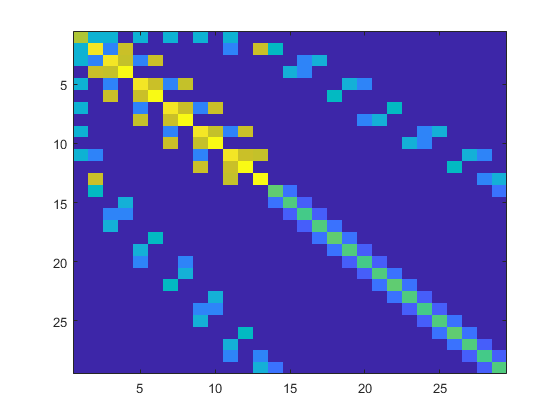

figure(2)
imagesc(log10(abs(PremierMembre)))

What can we say about the matrix? Is it sparse or full? Check that the non-zero entries are those you would expect just looking at the mesh.

## 4 Boundary integrals for the radiation condition and the known term

Here we compute the integrals necessary to enforce the radiation conditions on the boundary and to define the known terms.

These integrals are transformed into a sum of Hankel functions multiplied with Fourier transforms of the basis functions. We will truncate this summation for $i=-100,..., 100$. The variable "harmonics" wlll be used to define the sum limiting value 100.

### 4.1 Hankel function coefficients

Let us compute at first the coefficients involving the Hankel functions, and store all these coefficients in vector.

Let us compute at first the coefficients involving the Hankel functions, and store all these coefficients in vector.

The Hankel function of second kind $H_0^{(2)}(x)$ are computed with the command "besselh(i,2,x)" where "i" can be an array.

The derivative of the Hankel functions are computed with the formula $\frac{\text{d}}{\text{d}x}H_i^{(2)}(x)=\frac{1}{2}\left[H_{i-1}^{(2)}(x)-H_{i+1}^{(2)}(x)\right]$

% Computation of the coefficients in the summations
harmonics = 100;
i = -harmonics:harmonics;
Hank = besselh(i,2,k*a);
Hank_der = 1/2*(besselh(i-1,2,k*a)-besselh(i+1,2,k*a)) ;
coeff_boundary = (-0.5*k*a/pi) * (Hank_der./Hank);
coeff_known_term = 2.*1j.^(-i+1).*exp(-1j.*i.*theta_inc)./(pi*Hank);
coeff_boundary(102)

ans = 0.0947 + 0.2225i

coeff_known_term(102)

ans = 0.7923 - 0.5120i

Let us check that this step is correct. Again for the 29-node mesh, you should find for the $i=1$ elements of these coefficients

"coeff_boundary" value for $i=1$:    $-\frac{ka}{2\pi}\frac{H_1^{(2)}(ka)}{{H_1^{(2)}}'(ka)}=0.094732319269515 + j0.222463473000778$

"coeff_known_term" value for $i=1$:    $\frac{2j}{\pi}\frac{1}{{H_1^{(2)}}(ka)}je^{-j\theta}=0.792294935669666 - j0.511979127421531$

### 4.2 Boundary basis function transforms

The transforms of the boundary basis functions are known in closed form.

Their expressions require the computation of the angles associated to each node on the boundary. You can compute this with the command "angle" where the input is a complex number whose real part is the $x$ coordinate and the imaginary part is the $y$ cooordinate of the node.

After the computation of all the angles, you can compute the transforms. Be careful to treat in the correct way the first and the last basis function. The first basis function needs the angle coming from the last basis function, and vice versa...

The transforms can be stored in a matrix whose rows are the nodes, and the columns are the $i$ summation integers.

% Compute the phi angles associated to each boundary node
phi = zeros(1,no_boundary+2);
phi(1,1)=angle(X(end)+1j*Y(end));phi(1,2:end-1)=angle(X(boundary)+1j*Y(boundary));phi(1,end) =angle(X(1)+1j*Y(1));
phi=unwrap(phi);
% Computation of boundary matrix integrals
FEM_boundary_integ=zeros(no_vertices,2*harmonics+1);

for m=(1:no_boundary)+1
    for l=-harmonics:harmonics
        FEM_boundary_integ(boundary(m-1),harmonics+l+1) = (exp(1j*l*phi(m))/(l^2))*(((1-exp(-1j*l*(phi(m)-phi(m-1))))/(phi(m)-phi(m-1))) + ((1-exp(1j*l*(phi(m+1)-phi(m))))/(phi(m+1)-phi(m))));
    end
        FEM_boundary_integ(boundary(m-1),harmonics+1)=1/2*(phi(m+1) - phi(m-1));
end

FEM_boundary_integ(14,103)

ans = 0.3729 - 0.0000i

For the 29-node mesh, you should obtain for the $i=2$ integral of the basis function associated to the node 14:


$$\int_0^{2\pi}B_{14}(\varphi)e^{j2\varphi}\text{d}\varphi=0.372923228578057$$


### 4.3 Computation of the boundary sums and of the known term

Now we can compute the sums related to the boundary conditions (to be added to the FEM matrix) and the known term.

Example for the known term: multiply the vector "coeff_boundary" by the vector "FEM_boundary_integ" element-wise (with the operator .*). To sum over the $i$ index, use the command "sum", which sums all the entries of a 1-D vector variable.

Same process for the matrix entries coming from the boundary condition.

boundaryElement=sum(FEM_boundary_integ.*conj(FEM_boundary_integ).*coeff_boundary,2);
SecondMemebre=zeros(no_vertices);
for n=boundary
    for m=boundary
        SecondMemebre(m,n)=sum(FEM_boundary_integ(m,:).*conj(FEM_boundary_integ(n,:)).*coeff_boundary,2);
    end
end
A=SecondMemebre+PremierMembre;

b=sum(FEM_boundary_integ.*coeff_known_term,2);

b(14)

ans = -0.0946 - 0.0114i

b(16)

ans = 0.1135 - 0.1387i

For the 29-node mesh, you should obtain for the knwn term associated to the of the basis function associated to the nodes 14 and 16:


$$b(14)= -0.094641523340744 - j0.011400518573764$$



$$b(16)= 0.113547844400238 - j0.138743875232338$$


Let us now visualize again the entries of the FEM matrix, in a new graph. Which entries are now present? Is it a sparse or dense matrix?

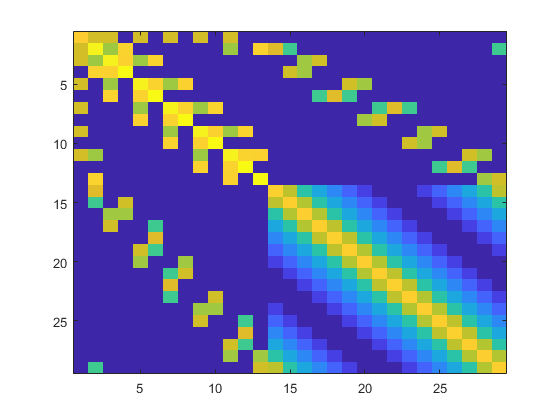

figure(5)
imagesc(log10(abs(A)))

## 7 Solution of the linear system

We wolve the FEM linear system, for exemple by means of the command "linsolve".

% % Solution of the linear system
e_z=linsolve(A,b);


## 8 Plot of the electric field along a cylinder diameter

We can plot the values of the total electric field $E_z$ along the diameter inside the cylinder $-r\le x\le r, y=0$. Select the correct nodes by looking at the mesh plotted at the beginning of the code.

if(no_vertices==29)
    %% For the model with 29 nodes
    n_plot = [2,1,7];   % indices of the nodes of the points where we want to measure the field
elseif(no_vertices==51)
    %% For the model with 51 nodes
    n_plot = [2,23,1,22,11];   % indices of the nodes of the points where we want to measure the field
end

x_plot = vertices(n_plot,1);
e_plot = e_z(n_plot);
e_inc_plot = e_z(n_plot) + e_z(n_plot)

e_inc_plot =   -0.2974 - 2.9769i
   1.2853 - 1.5447i
   0.5038 + 1.5572i


First of all, we can set the dieletric constant inside the cylinder to 1. The total electric field should be the same as the incident plane wave. Compare the result of the FEM in this case with the magnitude and phase of the incident field

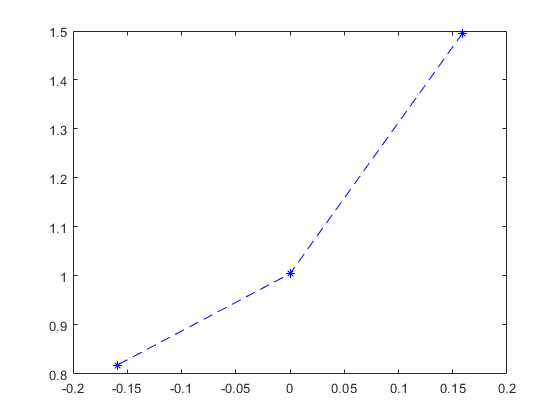

figure(6)
plot(x_plot,abs(e_plot),'b*--')       % Magnitude of the total electric field

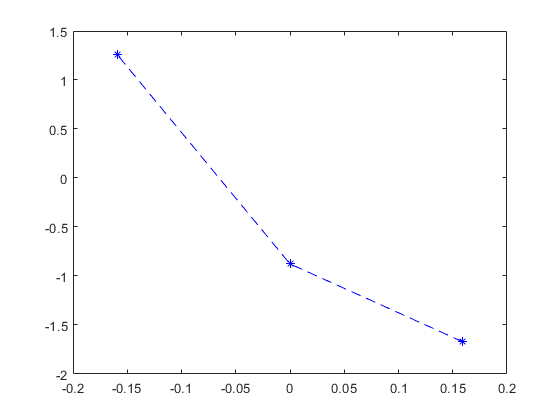

%hold on
%plot(x_plot,????????,'r-o')        % Magnitude of the incident electric field
figure(7)
plot(x_plot,angle(e_plot),'b*--')     % Phase of the total field

% hold on
% plot(x_plot,????????,'r-o')        % Phase of the incident electric field

Now run again the code with the correct dielectric constant inside the cylinder. We can compare the result on the same segment as before with the one in the following figure:

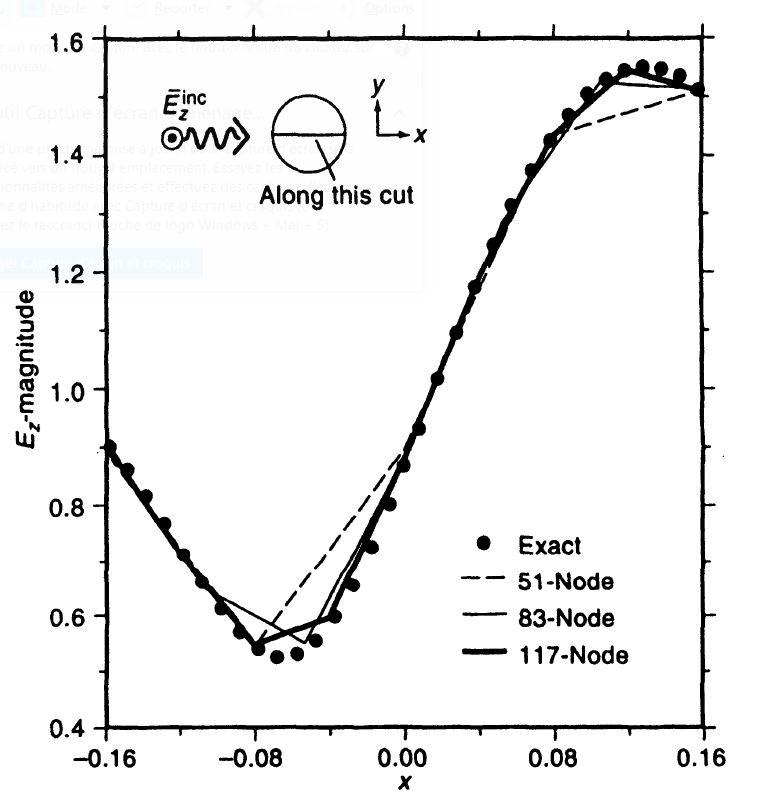

% figure(8)
% plot(??????,???????,'b-o')
% xlim([-0.16 0.16])
% ylim([0.4 1.6])
% pbaspect([1 1.16 1])

## 8 Comparison with the closed-form solution

We can also compare the total electric field in the center of the cylinder with the closed-form, computed in the following code.

Compare the relative accuracy of the result when you use 29 or 51 nodes.

% % Closed-form electric field at (0,0)
% radium=1/k; eps = 3;
% der_bes = -besselj(1,k*radium);
% bes = besselj(0,k*radium);
% der_bes_eps = -sqrt(eps)*besselj(1,k*sqrt(eps)*radium);
% bes_eps = besselj(0,k*sqrt(eps)*radium);
% hank = besselh(0,2,k*radium);
% der_hank = -besselh(1,2,k*radium);
% e_z_correct = (der_bes*hank-bes*der_hank)/(der_bes_eps*hank-bes_eps*der_hank);
% abs(e_z_correct)
% abs(...)   % put here the result of the FEM in the center of the cylinder (magnitude)
% angle(e_z_correct)*180/pi
% angle(...)*180/pi    % put here the result of the FEM in the center of the cylinder (phase)
% 
% % Relative-error computation in the center of the cylinder
% abs((...-e_z_correct)/e_z_correct)